# Sample 2-2

## 画像データの入出力

動画像処理 

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Input and output of images

Video processing

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 処理画像の準備

(Preparation of sample image)

本サンプルで利用する画像データを収めたdata フォルダにパスをとおして，サンプル動画を準備。

Create a path to the data folder that contains images used in this sample, and prepare a sample video.

addpath('./data')
close
% Preparation of a sample video
mkCalcioAvi

### 動画像サンプルの再生

(Video sample play)

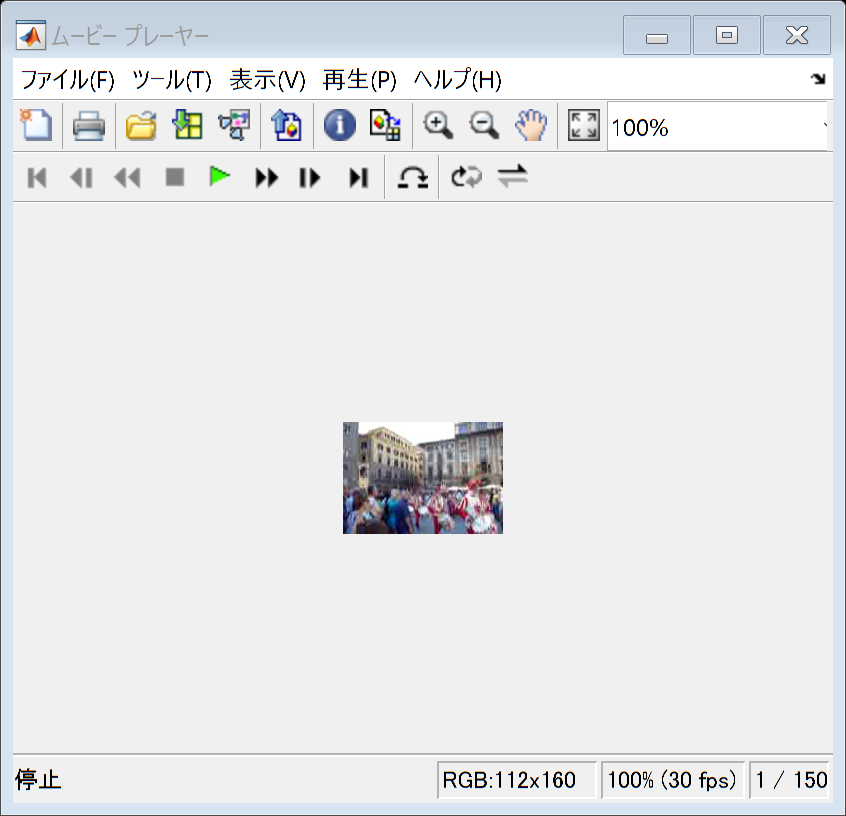

implay('calcio.avi');

### 入力動画の準備

(Preparation of input video)

VideoReaderオブジェクトの生成

Instantiation of VideoReader object

videoReader = VideoReader('calcio.avi');
frameRate   = videoReader.FrameRate;

### 出力動画の準備

(Preparation of output video)

VideoWriterオブジェクトの生成

非圧縮で保存

Instantiation of VideoWriter object

Save without any compression.

videoWriter  = VideoWriter('calcio_gray.avi','Uncompressed AVI');
videoWriter.FrameRate = frameRate;

### フレーム毎の処理

(Frame-by-frame processing)

フレームごとのグレースケール変換

Frame-by-frame grayscale conversion

videoWriter.open();
while(videoReader.hasFrame())
    % Reading frame
    pictureIn = videoReader.readFrame();
    % Frame processing
    pictureOut = rgb2gray(pictureIn);
    % Writing frame
    videoWriter.writeVideo(pictureOut);
end
videoWriter.close();

### 動画像処理結果の再生

(Output video play)

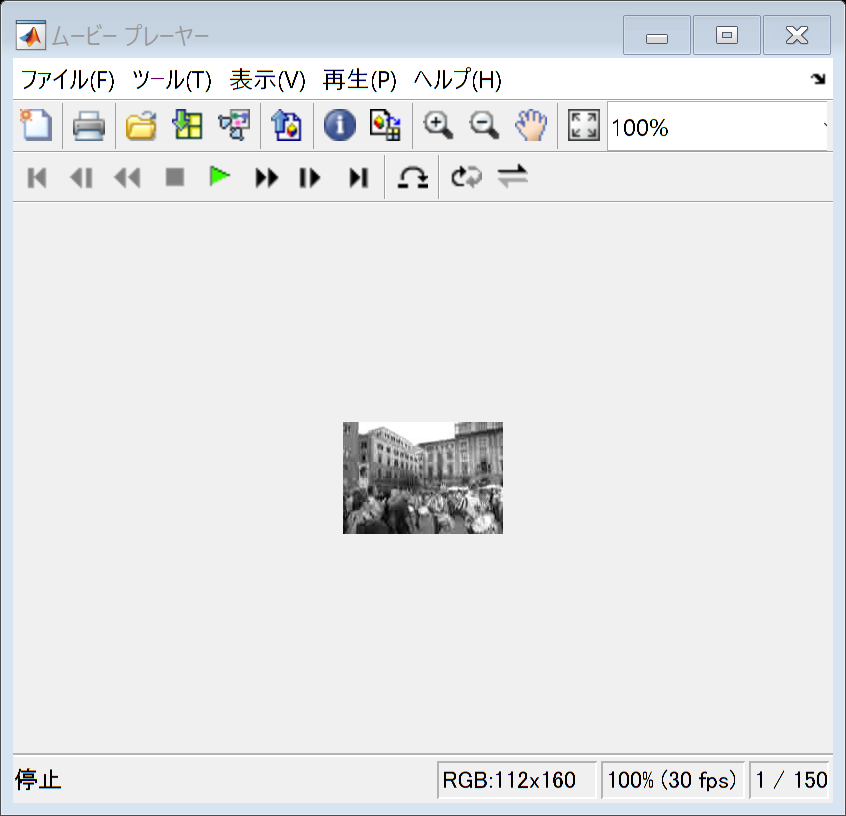

implay('calcio_gray.avi');

© Copyright, Shogo MURAMATSU, All rights reserved.